# TP2 : Simulation d’un processus SETAR

clc;
clear vars

## Exercice 1: Simulation d'un processus SETAR(1, 1)

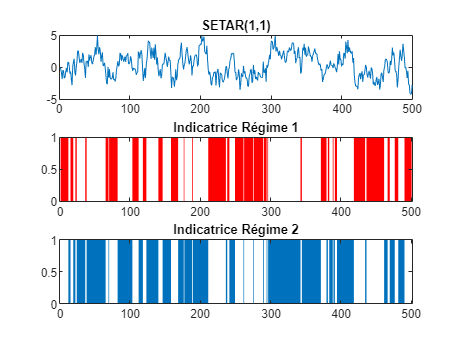

c1 = -0.5;
phi1 = 0.5;
sigma1 = 1;

c2 = 0.5;
phi2 = 0.7;
sigma2 = 1;

T = 500;
rng(100);

ind_haut = zeros(500,1);
ind_bas = zeros(500,1);
x = zeros(500,1);






for t=2:T
   x(t) = (c1+phi1*x(t-1)+randn(1))*(x(t-1)<=0) + ...
       (c2 + phi2*x(t-1) + randn(1))*(x(t-1)>0);
   ind_haut(t) = x(t-1)>0;
end

ind_bas(2:T) = x(1:T-1)<=0;

figure(1);
subplot(3,1,1),plot(x), title("SETAR(1,1)");
subplot(3,1,2),bar(ind_bas,1,'r'), title("Indicatrice Régime 1");
subplot(3,1,3),bar(ind_haut,1), title("Indicatrice Régime 2");

## Exercice 2: Identification de l'ordre du processus

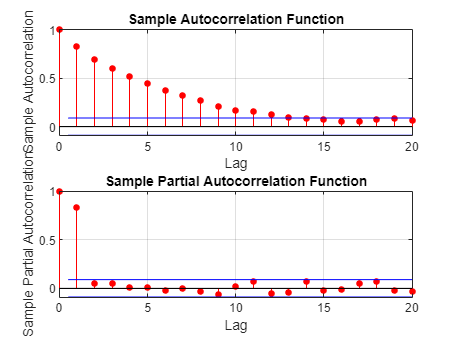

figure(2)
subplot(2,1,1),autocorr(x)
subplot(2,1,2),parcorr(x)

## Exercice 3: Estimation du processus SETAR

% LORSQUE LAMBDA-SEUIL EST CONNU (0)
% JE SAIS ESTIMER MON MODELE CAR JE PEUX CONSTRUIRE LA MATRICE X
% GRACE AUX MCO

seuil = 0;

y = x(2:T, 1);

cst = ones(T-1, 1);
x_1 = x(1:T-1, 1);
indic = x_1 <= seuil;

X =     1.0000         0         0         0
    1.0000   -0.3391         0         0
    1.0000   -0.9085         0         0
    1.0000   -1.8557         0         0
    1.0000   -0.4799         0         0
    1.0000   -0.6428         0         0
    1.0000   -1.7381         0         0
    1.0000   -1.5932         0         0
    1.0000   -0.7764         0         0
    1.0000   -0.1222         0         0



X = [cst.*indic x_1.*indic cst.*(1-indic) x_1.*(1-indic)]

% beta = (c1, phi1, c2, phi2)
bet = inv(X'*X)*X'*y;
bet1 = regress(y, X)

bet1 =    -0.5734
    0.4978
    0.4009
    0.7026


e = y - X*bet;
var_e = e'*e/(T-1)

var_e = 1.0059


% LORSQUE LAMBDA-SEUIL EST INCONNU: BOUCLE SUR SEUILS %
y_1 = x(1:T-1);
cst = ones(T-1, 1);
seuil_tri = sort(y_1);
seuil_range = seuil_tri(round(0.15*(T-1)):round(0.85*(T-1)))';
var_min = 10^10;

for seuil = seuil_range
    
    indic = y_1 < seuil;
    X = [cst.*indic y_1.*indic cst.*(1-indic) y_1.*(1-indic)];
    
    bet = inv(X'*X)*X'*y;
    e = y-X*bet;
    var_e = e'*e/(T-1);
    
    if var_e < var_min
        var_min = var_e;
        seuil_opt = seuil;
        X_opt = X;
        e_opt = e;
        bet_opt = bet;
    end
end
var_min

var_min = 1.0059

X_opt

X_opt =     1.0000         0         0         0
    1.0000   -0.3391         0         0
    1.0000   -0.9085         0         0
    1.0000   -1.8557         0         0
    1.0000   -0.4799         0         0
    1.0000   -0.6428         0         0
    1.0000   -1.7381         0         0
    1.0000   -1.5932         0         0
    1.0000   -0.7764         0         0
    1.0000   -0.1222         0         0


e_opt

e_opt =     0.2343
   -0.1664
   -0.8301
    1.0172
    0.1694
   -0.8448
   -0.1547
    0.5900
    0.8376
   -0.1891


bet_opt

bet_opt =    -0.5734
    0.4978
    0.4009
    0.7026


seuil_opt

seuil_opt = 0.0011

## Exercice 4: Tests de diagnostic

[~, p_val_lbq] = lbqtest(e_opt, 'lags', [5 10 20])

p_val_lbq =     0.6920    0.7323    0.6853


[~, p_val_arch] = lbqtest(e_opt.^2, 'lags', [5 10 20])

p_val_arch =     0.8871    0.9281    0.8859


[~, p_val_jb] = jbtest(e_opt)

p_val_jb = 0.5000


% p_val_jb > 5% => résidus identiquement, indépendaments et normalement distribués

varbet = var_min * inv(X_opt'*X_opt);
sigbet = sqrt(diag(varbet));

% test de significativité
tstat = bet_opt ./ sigbet; pval = 2*(1-normcdf(abs(tstat)))

pval = 	1.0e+-3 *

    0.0045
    0.0000
    0.2006
         0


% DGP : Data Generating Process - CE QUE J'ESPERE OBTENIR
bet_dgp = [-0.5; 0.5; 0.5; 0.7]

bet_dgp =    -0.5000
    0.5000
    0.5000
    0.7000



titre = {'Paramètres DGP' 'Params Estimés' 't_stat' 'p_val'}

titre = 1×4 cell array
    {'Paramètres DGP'}    {'Params Estimés'}    {'t_stat'}    {'p_val'}


valeurs = [bet_dgp bet_opt tstat pval]

valeurs =    -0.5000   -0.5734   -4.5846    0.0000
    0.5000    0.4978    6.6744    0.0000
    0.5000    0.4009    3.7182    0.0002
    0.7000    0.7026   13.3177         0


table(titre', valeurs')

ans = 4×2 table
           Var1                                   Var2                        
    __________________    ____________________________________________________

    {'Paramètres DGP'}          -0.5           0.5           0.5           0.7
    {'Params Estimés'}      -0.57336       0.49776       0.40093       0.70258
    {'t_stat'        }       -4.5846        6.6744        3.7182        13.318
    {'p_val'         }    4.5484e-06    2.4821e-11    0.00020063             0


## Exercice 5 : Test de Linéarité - Statistique de Wald

R = [1 0 -1 0; 0 1 0 -1];
r = zeros(2,1);

Wald = var_min^(-1) * (R*bet_opt - r)' * inv(R*(X_opt'*X_opt)^-1*R')*(R*bet_opt - r)

Wald = 35.9668



Xlin = [cst x_1(1:T-1)]

Xlin =     1.0000         0
    1.0000   -0.3391
    1.0000   -0.9085
    1.0000   -1.8557
    1.0000   -0.4799
    1.0000   -0.6428
    1.0000   -1.7381
    1.0000   -1.5932
    1.0000   -0.7764
    1.0000   -0.1222



betlin = regress(y, Xlin)

betlin =     0.0581
    0.8325


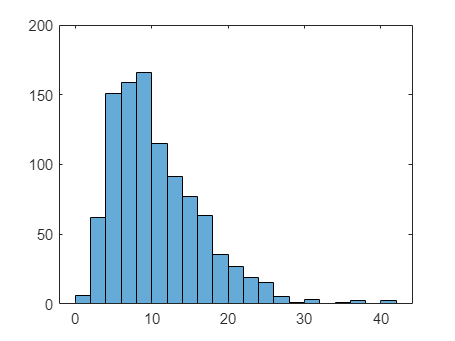

elin = y - Xlin*betlin;
siglin = sqrt(elin'*elin)/T-1;

Wsim = zeros(1000,1);
AR= zeros(1000,1);

for i = 1:1000
    for t = 2:T
        AR(t,1) = betlin(1) + betlin(2)*AR(t-1,1) + siglin*randn;
    end
    %calc Wald stat (func testlin setar1)
    Wsim(i) = testlin_setar1(AR);
end

%histo Wsim
figure(4);histogram(Wsim);

%calcul vcritique (quantile 95%)
vc_wald = quantile(Wsim, 0.95)

vc_wald = 21.9159


% Rejet H0 car Wald > Wsim(95%)